# AutoFFT v1.5.5 - User Manual

## License Information

This code is published under BSD-3-Clause License. Copyright © 2017-2025, authors.

### Contact

Please, report any issue at [https://github.com/LubosSmolik/autofft/issues](https://github.com/LubosSmolik/autofft/issues).

Alternatively, you can use e-mail smolik{at}vzuplzen.cz

### Authors

**Lead developer: **Luboš Smolík, VZÚ Plzeň (Research and Testing Institute Plzeň) & University of West Bohemia                      

**Lead tester: **Jan Rendl, University of West Bohemia

**Tester, new functionalities:** Roman Pašek, VZÚ Plzeň (Research and Testing Institute Plzeň)

## Introduction

Signal Processing Toolbox™ provides several functions to power spectrum estimation, including `pspectrum, pwelch` and `stft`. While these functions are high-quality and well-documented, they can be cumbersome for certain engineering applications. These applications include estimating magnitudes of vibration, noise and other discrete-time signals in engineering units or comparing theoretical results with measurements.

The `autofft` package is designed to address these needs by mimicking the operation of Brüel & Kjær FFT analysers. Based on user input, `autofft` automatically filters the signal, divides it into segments, applies window functions, and performs spectral averaging. The resulting averaged spectrum, also called *modified periodogram*, can be returned in various engineering spectral units, including decibels, root mean square (RMS) and peak-to-peak magnitudes, and power spectral density (PSD). In addition, `autofft` can compute spectral derivatives and integrals, as well as perform short-time Fourier transform (STFT) analysis.

### Key features

- **No toolbox dependency** - works without Signal Processing Toolbox™.

- **High performance** - performs significantly better than `pwelch` and `pspectrum` in computationally intensive problems.

- **Works with engineering units** - works not only with relative units (dB) but also with engineering units (EU), such as RMS, peak-to-peak or power spectral density.

- **Configurable analyser setup** - provides greater control over the setup of the frequency analyser than built-in functions.

- **Built-in filtering** - can apply high-pass filters in the time domain.

- **Advanced post-processing** - can apply frequency weighting filters per IEC 61672-1:2013, spectral derivation or spectral integration.

### What's new?

- **v1.5.5:** *Bug fix*: Uncommented text preventing use of custom filters has been removed.

- **v1.5.5:** *Bug fix*: Erroneous coefficient that caused bandstop filters to be generated incorrectly using autoButter function has been corrected.

- **v1.5.5**: *Code optimisation*: Generation of windows with a very large number of samples has been optimised.

- **v1.5.4:** *Bug fix*: Automatic plotter no longer uses white backgroud color in R2025a dark mode.

- **v1.5.4:** *Bug fix*: Plotting error when the user selected tiled layout for time-frequency analysis results from only one channel has been fixed.

- **v1.5.4:** *Code optimisation*: Evaluation of magnitude and spectral unit has been optimised. Other minor optimisations implemented and code refactored. CPU time reduced by up to 35 %.

- **v1.5.4:** *Code optimisation*: Error handling during filtering has been improved.

- **v1.5.4:** *Documentation*: Introduction has been revised.

### Compatibility and requirements

- Created with R2025a

- Compatible with R2016b to R2025a

## Syntax

## Description

`autofft(xs, fs)` computes and diplays the autospectrum or spectrogram of input `xs` using sampling frequency `fs` in Hz. `xs` can be either a vector or an array consisting of column vectors. In the latter case, each spectrum or spectrogram is shown in a separate figure.

`autofft(xs, ts)` computes and diplays the autospectrum or spectrogram of input `xs` using a vector of time stamps `ts`.

`autofft(___, setup)` computes and diplays the autospectrum or spectrogram of input `xs` using name-value pair arguments specified in a structure array `setup`.

`s = autofft(___)` computes and returns autospectrum or the short-time Fourier transform (STFT) of input `xs`. Does not visualise the results unless specified in `setup`.

`[s, f] = autofft(___)` also returns the vector of frequencies `f` at which the autospectrum or STFT of input `xs `are evaluated.

`[s, f, setup] = autofft(___)` also returns the `setup` of the FFT analyser if `s` is the autospectrum.

`[s, f, t] = autofft(___)` also returns the vector of times `t` at which the STFT slices are evaluated if the STFT is performed.

`[s, f, t, setup] = autofft(___)` returns all information available.

## Examples

### Estimate autospectrum of a single signal

Generate a testing voltage signal with a duration of 1 second, which contains harmonic components at 80 Hz and 150 Hz.

dt = 1e-3;                                      % Sampling period (s)
T  = 1;                                         % Signal duration (s)
t  = dt:dt:T;                                   % Time vector 
S  = sin(2*pi*50*t) + 0.5 * sin(2*pi*150*t);    % Voltage (V)

Corrupt the signal with zero-mean white noise with a variance of 4.

X = S + 2*randn(size(t));

Estimate the autospectrum of the noisy signal.

[s, f] = autofft(X, t);

Plot the result. The magnitudes are roughly squares of the effective values (RMS). The discrepancies are present due to the added noise. The effect of the noise can be reduced by spectral averaging, which is described in section Spectral Averaging.

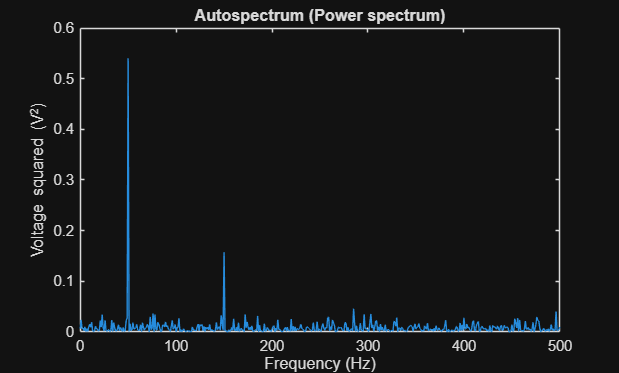

figure;
plot(f, s);
xlabel("Frequency (Hz)")
ylabel("Voltage squared (V^2)")
title("Autospectrum (Power spectrum)")

#### Modify the analyser setup

Using vector `X` from the previous example, one can check a setup used by the FFT analyser using the following code:

[s, ~, setup] = autofft(X, t);

Now, the setup can be displayed.

disp(setup)

       SamplingFrequency: 1000
            DataDuration: 1
              DataLength: 1000
               FFTLength: 1000
          TimeResolution: 1
     FrequencyResolution: 1
                    Mode: "onesided"
       HighPassFrequency: NaN
        LowPassFrequency: 500
                  Window: "uniform"
    WindowNoiseBandwidth: 1
           OverlapLength: 500
       OverlapPercentage: 50
               Averaging: "linear"
        NumberOfAverages: 1
             jwWeigthing: "none"
            SpectralUnit: "power"
         EngineeringUnit: "EU"
             dbReference: NaN
              PlotLayout: "none"



Change the `'SpectralUnit'` parameter to `'rms'`  and use the modified setup in the FFT analyser.

setup.SpectralUnit = "rms";
[sRMS, f, setup] = autofft(X, t, setup);
disp(setup)

       SamplingFrequency: 1000
            DataDuration: 1
              DataLength: 1000
               FFTLength: 1000
          TimeResolution: 1
     FrequencyResolution: 1
                    Mode: "onesided"
       HighPassFrequency: NaN
        LowPassFrequency: 500
                  Window: "uniform"
    WindowNoiseBandwidth: 1
           OverlapLength: 500
       OverlapPercentage: 50
               Averaging: "linear"
        NumberOfAverages: 1
             jwWeigthing: "none"
            SpectralUnit: "RMS"
         EngineeringUnit: "EU"
             dbReference: NaN
              PlotLayout: "none"



Plot the results.

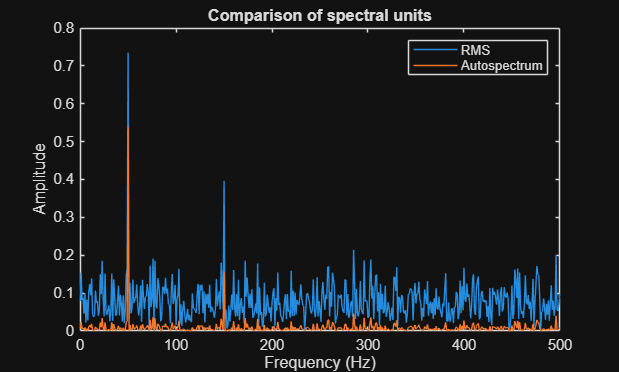

figure;
plot(f, [sRMS, s]);
xlabel("Frequency (Hz)")
ylabel("Amplitude")
title("Comparison of spectral units")
legend("RMS", "Autospectrum")

The structure containing the analyser setup can also be constructed field by field. In such a case, field names and their values are case insensitive, and unspecified fields are generated internally by the `autofft` function.

userSetup = struct("spectralunit", "rms");

Use `userSetup` in the FFT analyser and compare the resulting spectrum with the previously computed spectrum stored in variable `sRMS`.

sRMS2 = autofft(X, t, userSetup);
maxError = max(abs(sRMS - sRMS2));
disp("Maximum difference between sLin and sLin2 is " + maxError)

Maximum difference between sLin and sLin2 is 0


### Analyse a signal using the decibel scale

Decibel scales, defined in section Decibels, are widely used in several engineering branches, including control, acoustics and electronics. They are instrumental when dealing with signals that contain components differing by several orders of magnitude. Such signals are typically produced by acoustic sources. Let us generate a sound pressure waveform from a tuning fork at A (440 Hz). The waveform will contain a sinusoidal wave at the fundamental frequency 440 Hz (the first harmonic) and also some higher harmonics. The second harmonic is the most prominent higher harmonic. However, it will be about [one or two orders of magnitude smaller than the first harmonic](https://www.comsol.com/blogs/finding-answers-to-the-tuning-fork-mystery-with-simulation/) [1]. In addition to the harmonics, the measured signal will also contain ambient noise. 

fbase = 440;    % Frequency of the tuning fork  (Hz)
h1mag = 0.5;    % Magnitude of the 1st harmonic (Pa)
h2mag = 0.01;   % Magnitude of the 2rd harmonic (Pa)
nvar  = 0.06;   % Standard deviation of noise   (Pa)
fs = 4096;      % Sampling frequency (Hz)
ns = 2 * fs;    % Number of samples   (-)

t = 1/fs:1/fs:ns/fs; % Vector of time
p = h1mag * sin(2 * pi * fbase * t) + h2mag * sin(4 * pi * fbase * t);

% Add normally distributed ambient noise
p = p + nvar * randn(size(p));

If the power spectrum estimated by the FFT analysis is depicted in the linear scale, the only visible frequency component is the first harmonic.

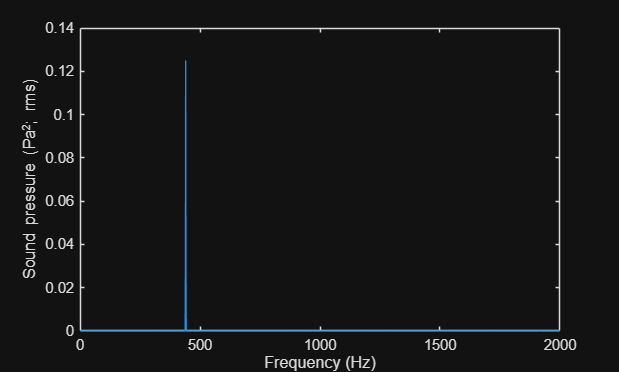

% Perform the FFT analysis
[s, f] = autofft(p, fs, struct("FrequencyResolution", 1, "Window", "Hann"));

% Plot results
plot(f, s)
xlabel("Frequency (Hz)");
ylabel("Sound pressure (Pa^2; rms)")
xlim([0 2000]);

Other components contained in the power spectrum are visible only if the logarithmic or decibel scale is used. The following example shows how to set the parameters of `autofft` so that the power spectrum is computed in decibels. First, a reference value has to be specified. Since this example deals with the sound pressure, the reference value should be $p_{\textrm{ref}} =20\;\textrm{mPa}\;\left(\textrm{rms}\right)$. 

% Set the reference value for the decibel scale
pref = 2e-5;  

If the appropriate reference value is unknown to the user, they can set it to $0$. In such a case, `autofft` selects the reference value so that the maximum in the computed spectra is 0 dB.

Now perform the FFT analysis and plot the results. The second harmonic is clearly visible at 880 Hz, its signal-to-noise ratio is slightly more than 10 dB.

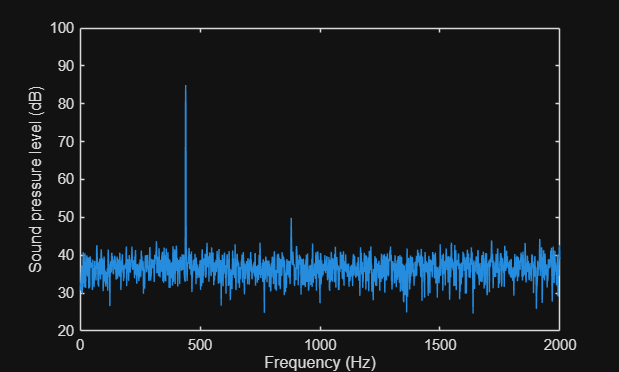

% Perform the FFT analysis
[spl, f] = autofft(p, fs, struct("FrequencyResolution", 1,"Window", "Hann", ...
                                 "dbReference", pref));
% Plot results
plot(f, spl)
xlabel("Frequency (Hz)");
ylabel("Sound pressure level (dB)");
xlim([0 2000]);
ylim([20 100]);

**Remark 1: **The human ear is less sensitive to sounds at specific frequencies. This phenomenon should be considered when assessing potential hearing damage, analysing audio equipment or performing tests dealing with the human perception of sound. A standardised sensitivity of the human ear is given by frequency weighting filters defined in the International standard IEC 61672:2003. Two most commonly used filters are called A-weighting and C-weighting. Other filters denoted B, D and M are also sometimes used.

These filters can be applied directly on the power spectrum using the freqWeight function, which has been included in the autofft releases since v1.5.0. 

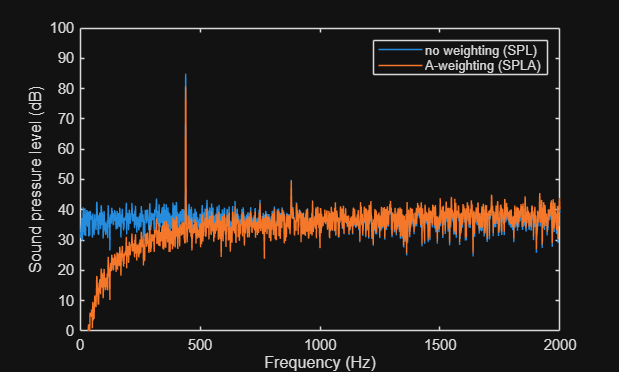

% Apply frequency weighting filter to the power spectrum
splA = freqWeight(spl, f, "A");

% Plot results
plot(f, [spl splA]);
xlabel("Frequency (Hz)");
ylabel("Sound pressure level (dB)");
xlim([0 2000]);
ylim([0 100]);
legend("no weighting (SPL)", "A-weighting (SPLA)")

### Estimate autospectra of multiple signals

Generate three testing voltage signals with a duration of 2 seconds with various harmonic components.

dt = 1e-3;                                          % Sampling period (s)
T  = 2;                                             % Signal duration (s)
t  = dt:dt:T;                                       % Time vector
S1 = sin(2*pi*50*t) + 0.5 * sin(2*pi*150*t);        % Signal 1 (V)
S2 = 0.7 * sin(2*pi*80*t) + 0.5 * sin(2*pi*100*t);  % Signal 2 (V)
S3 = 0.8 * sin(2*pi*90*t) + 0.9 * sin(2*pi*120*t);  % Signal 3 (V)

Arrange the testing signals into an array and corrupt the signals with zero-mean white noise with a variance of 1. Note that the testing signals have to be converted to **column vectors**.

X = [S1(:), S2(:), S3(:)];
X = X + randn(size(X));

Construct the structure containing the analyser setup and divide the testing signals into 1 s long segments using the `'TimeResolution'` parameter. The segments are overlapping by 75 % and the Hann window is applied. The magnitude of the resulting spectra is equal to a zero-to-peak value.

setup = struct("TimeResolution", 1, "Window", "hann", ...
               "OverlapPercentage", 75, "SpectralUnit", "peak");

Estimate the autospectra of the testing signals and plot results.

[s, f] = autofft(X, t, setup);
disp(setup)

       TimeResolution: 1
               Window: "hann"
    OverlapPercentage: 75
         SpectralUnit: "peak"



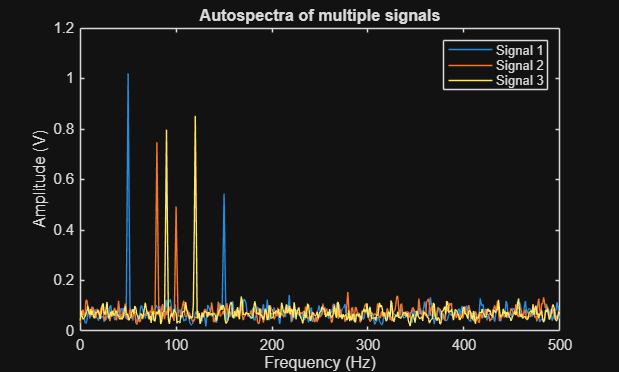

figure;
plot(f, s);
xlabel("Frequency (Hz)")
ylabel("Amplitude (V)")
title("Autospectra of multiple signals")
legend("Signal 1", "Signal 2", "Signal 3")

### Automatic visualisation of the results

`autofft` can visualise results automatically by calling the main function without output variables, i.e.:

If more than one signal is analysed, each spectrum or spectrogram is plotted in a separate figure. This behaviour can be changed using the `'PlotLayout'` parameter. By default, the `'PlotLayout'` parameter is set to:

- `'PlotLayout' = 'none'` if the `auttofft` function is called with no output variables, or

- `'PlotLayout' = 'separated'` if the `auttofft` function is called with at least one output variable.

Two other options are available:

- `'PlotLayout' = 'stacked'`, which plots all results into single axes (this value cannot be used to visualise spectrograms), and

- `'PlotLayout' = 'tiled'`, which creates panels with individual spectra or spectrograms in a single figure.

Users can also specify the `'EngineeringUnit'` parameter, which serves to generate label of the vertical axis.

Now, add the `'PlotLayout'` and `'EngineeringUnit'` parameters to the existing setup and visualise the results of the freqeuncy analysis.

setup.PlotLayout = "stacked";
setup.EngineeringUnit = "V";
autofft(X, t, setup);

Change the `'PlotLayout'` to visusalise the results in tiled panels.

setup.PlotLayout = "tiled";
autofft(X, t, setup);

### Perform a time-frequency analysis of a single signal

Generate two seconds of a voltage controlled oscillator output, controlled by a sinusoid sampled at 10 kHz.

fs = 10e3;                      % Sampling frequency (Hz)
t  = 0:1/fs:2;                  % 2 secs at 10 kHz sample rate (s)
fmin = 1000;                    % Minimum frequency (Hz)                    
fmax = 4000;                    % Maximum frequency (Hz)
fosc = 1;                       % Rate at which frequency changes from fmin to fmax to fmin

fc = (fmax + fmin) / 2;         % Central frequency (Hz)
k = 2 * pi * (fmax - fc) / fs;  % Coefficient for frequency oscillations

% Oscillator output (V)
x = cos(2 * pi * fc * t + k * cumsum(sin(2 * pi * fosc * t)));

Perform the short-time Fourier transform (STFT) of the signal and plot the results. Use a Kaiser window of length 256 and shape parameter $\beta =5$. Specify the length of overlap as 220 samples and the frequency resolution as 40 Hz. The spectral unit of the STFT is set to zero-to-peak. Note that in contrast to the `stft` function, additional parameter `'Averaging'` has to be set to `'none'`. This parameter switches the output from the averaged autospectrum to to the STFT.

setup = struct("FrequencyResolution", 40, "Window", utilities.autoKaiser(256,5), ...
               "OverlapLength", 220, "SpectralUnit", "peak", "Averaging", "none");
[s, f, t, ~] = autofft(x, fs, setup);

Note that if the window length does not correspond with the FFT length, autofft uses an interpolated window function. Now, plot the spectrogram with default colormap and view.

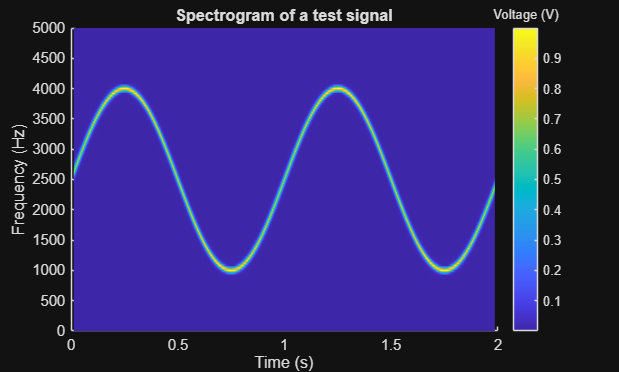

figure;
surface(t, f, s);
shading interp;
xlabel("Time (s)")
ylabel("Frequency (Hz)")
title("Spectrogram of a test signal")
c = colorbar;
title(c, "Voltage (V)")

### Perform a time-frequency analysis of multiple signals

Generate a control parameters for a quadratic chirp sampled at 1 kHz:

ts = 0:0.001:2; % 2 secs at 1 kHz sample rate (s)
f0 = 100;       % Frequency at t0 (Hz)
t1 = 1;         % Time t1
f1 = 200;       % Frequency at t1 (Hz)
n  = 2;         % Order of the chirp

% Compute beta so that f(t0) = f0
beta = (f1 - f0) * (t1 ^ (-n));

Generate the chirp of length 2 s and corrupt it with zero-mean white noise and arrange  both original and corrupted chirps into a single array. Note that the testing signals have to be converted to **column vectors**.

yq    = cos(2 * pi * (beta ./ (1 + n) * (ts.^(1 + n)) + f0 * ts));
yqCor = yq + randn(size(yq));
ych   = [yq(:), yqCor(:)];

Compute and plot the STFT of both chirps. Set the frequency resolution to 10 Hz and use a Blackmann-Harris window with overlap 90 %.

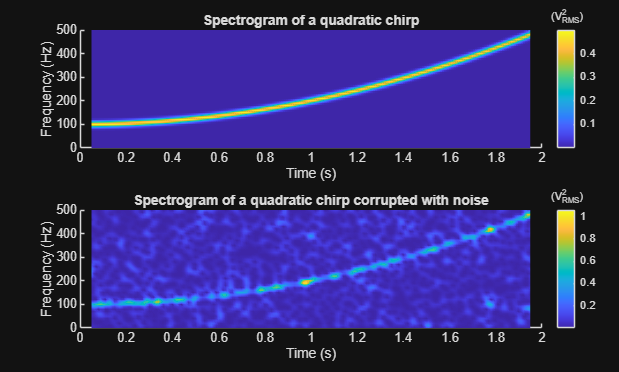

setup = struct("FrequencyResolution", 10, "Window", "b", ...
               "OverlapPercentage", 90, "Averaging", "none");
[s, f, t, setup] = autofft(ych, ts, setup);

tiledlayout(2, 1);
nexttile;
surface(t, f, squeeze(s(:,:,1)));
ylim([0 f(end)]);
shading interp;
xlabel("Time (s)")
ylabel("Frequency (Hz)")
title("Spectrogram of a quadratic chirp")
c = colorbar;
title(c, "(V_{RMS}^2)")

nexttile;
surface(t, f, squeeze(s(:,:,2)));
ylim([0 f(end)]);
shading interp;
xlabel("Time (s)")
ylabel("Frequency (Hz)")
title("Spectrogram of a quadratic chirp corrupted with noise")
c = colorbar;
title(c, "(V_{RMS}^2)")

## Detailed Description of the Analyser Setup

This section makes use of Refs. [2-5].

### Analyser resolution

The frequency resolution $\Delta f$ is the difference in frequency between two consecutive spectral lines (bins). Two signal components are indistinguishable if their frequencies $f_1$ and $f_2$ are close relative to the frequency resolution. By rule of thumb, two independent components should be separated at least by one spectral line if the uniform window is used, i.e. $\left|f_1 -f_2 \right|\ge 2\cdot \;\Delta f$.

**Remark:** In real applications, the minimum frequency separation depends on so-called *spectral leakage. *Due to this phenomenon, energy can "leak" from a certain line into the adjacent spectral lines. The spectral leakage happens due to assumption that the analysed signal is periodic which causes the distortion of signals, which are not perfectly periodic, and also due to the fact that frrequencies of components contained in the signals do not coincide with the frequencies of the spectral lines. More information on the spectral leakage can be found in the Applying a window function section.

Consider the analysed signal contains $N_s$ samples and is sampled by sampling frequency $f_s$ in Hz. Then the total length of the analysed signal in s is


$$T=\frac{f_s }{N_s }\ldotp$$


**By default**, the analysed **signal is treated as one segment**, but it can be divided into multiple segments, each containing $n_s$ samples. The frequency resolution $\Delta f$ is then determined by the length of the segment:


$$\Delta f=\frac{f_s }{n_s }=\frac{1}{T_s },$$


where $T_s$ is the length of the segment in s. Overlapping of adjoining segments is explained hereafter.

The short-time Fourier transform (STFT) serves to analyse signals in time and frequency. Therefore, the user should consider both time resolution and frequency resolution. The equation above suggests that good frequency resolution requires the use of long segments. However, if the long segment contains a short transient, it is impossible to estabilish an exact time when this transient occurs. On the other hand, shortening the segments improve time resolution at the cost of frequency resolution. The analyser resolution can be adjusted using one of the following parameters:

`'FFTLength'`** — Number of DFT points**

`total number of samples (default) | positive integer`

If `'FFTLength'` $n_s$ is provided, then the analysed signal is divided into segments with each containing $n_s$ samples.

**Data type:**` double | single`

`'TimeResolution'`** —  Length (in seconds) of the DFT**

`duration of the signal (default) | positive scalar`

If `'TimeResolution'` $T_s$ is provided, then  the analysed signal is divided into segments with each containing $T_s \cdot f_s$ samples.

**Data type:**` double | single`

`'FrequencyResolution'`** — Desired frequency resolution of the DFT**

`fs / size(xs, 2) (default) | positive scalar`

Use this parameter if you want to control the freqeuncy resolution $\Delta f$ directly. If `'FrequencyResolution'` $\Delta f$ is provided, then the analysed signal is divided into segments with each containing $f_s \;/\;\Delta f$ samples.

**Data type:**` double | single`

**Remark 1:** If the user-specified number of samples per segment is higher than actual length of the analysed signal , the value of $n_s$ is internally set to $n_s =N_s$.

**Remark 2:** If `'FFTLength'` is set, then both `'TimeResolution'` and `'FrequencyResolution'` are ignored by the analyser. If `'TimeResolution'` is set, then `'FrequencyResolution'` is ignored by the analyser. This behaviour is different from the `stft` function, where `'FFTLength'` and `'TimeResolution'` can be adjusted independently.

### Analyser mode

`'Mode'`** — Analyser mode to use**

`'onesided' (default) | 'twosided'`

- `'onesided'` - Computes a one-sided autospectrum or STFT over the interval $\left\langle 0,{\;f}_{\max } \right\rangle ,$ where value ${\;f}_{\max }$ is given by the `'LowPassFrequency'` parameter.

- `'twosided'` - Computes a two-sided, centered autospectrum or STFT over the interval $\left\langle -f_{\max } ,{\;f}_{\max } \right\rangle ,$ where value ${\;f}_{\max }$ is given by the `'LowPassFrequency'` parameter.

**Data type:**` char | string`

### High-pass filtering

`'HighPassFrequency'`** — Passband frequency of the high-pass filter**

`NaN (default) | real number`

The high-pass filter is often chosen if the analysed signal is contaminated with low-frequency data or a constant offset (DC), which is not in the interest frequency range. `autofft` has a built-in function to design a first-order Butterworth digital high-pass filter with a variable passband frequency. The designed filter has attenuation lower than -0.05 dB at passband frequency $f_{\textrm{pass}}$ and has a fixed attenuation -3 dB at cut-off frequency $f_{\textrm{cut}} =0\ldotp 1\cdot f_{\textrm{pass}}$. The slope of the filter below $f_{\textrm{cut}}$ is -20 dB/dec as can be seen in fig. 1. The filter specification corresponds with high-pass filters used in **Brüel & Kjaer** **IDAe** **modules**. Passband frequency $f_{\textrm{pass}}$ can be either negative, zero or positive. The sign controls the behaviour of the filter:

- If $f_{\textrm{pass}}$ is not a number (`NaN`) or `'HighPassFrequency'` is not provided, no high-pass filter is applied.

- If $f_{\textrm{pass}} =0$, only the direct (DC) component is removed with the use of the `detrend` function.

- If $f_{\textrm{pass}} >0$, the `detrend` function is applied and the high-pass filter with the specified passband frequency is applied subsequently.

- If $f_{\textrm{pass}} <0$, then only the high-pass filter with passband frequency $\left|f_{\textrm{pass}} \right|$ is applied.

**Data type:**` double | single`

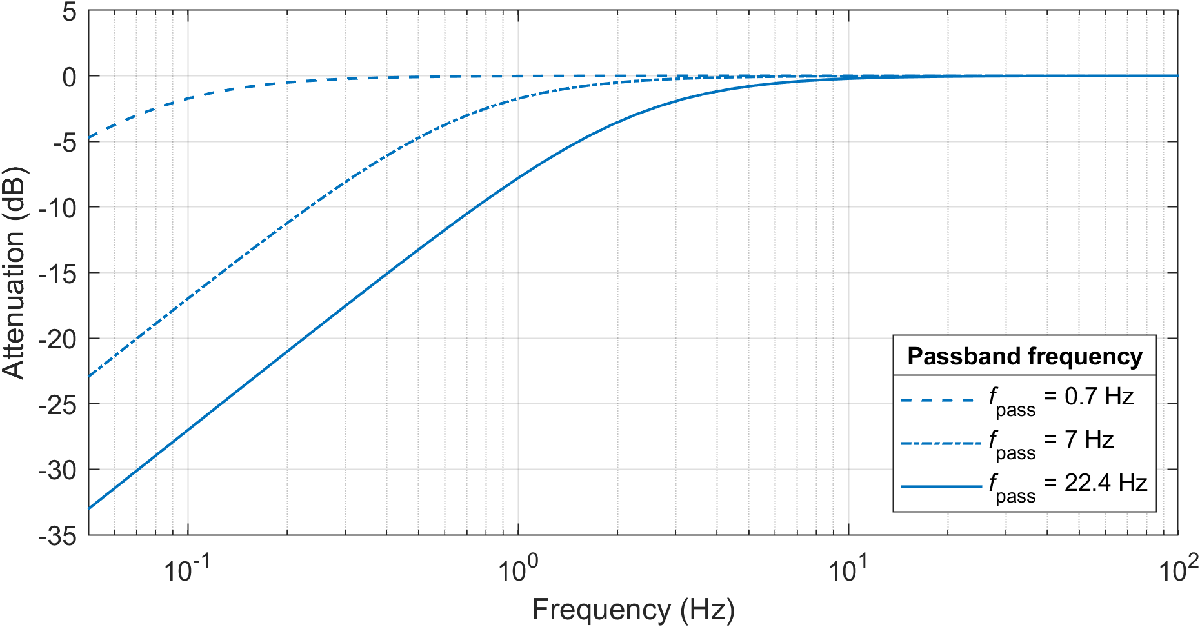

**Figure 1**: Magnitude response of several first-order Butterworth filters constructed by `utilities.autoButter` function.

### Low-pass filtering

`'LowPassFrequency'`** — Maximum frequency of interest**

`half of the sampling frequency (default) | positive scalar up to half of the sampling frequency`

In the current version of `autofft`, `'LowPassFrequency'` is used to specify the maximum frequency of interest. Data at higher frequencies are not used for the spectral averaging and evaluation of spectral units and are not returned in output variables. No low-pass filter is applied in the time domain. Therefore, you can use this parameter to limit the output frequency range and slightly speed up computations. The **recommended** maximum value of `'LowPassFrequency'` is $f_{s\;} /2\ldotp 56$, where $f_{s\;}$ is the sampling frequency.

**Data type:**` double | single`

### Applying a window function

`'Window'`** — Applied window function / time weighting**

`'uniform' (default) | 'blackmann' | 'flat-top' | 'hann' | 'hamming' | 'kaiser' | 'kaiserA.B' | vector`

When you apply a window function, each segment of the analysed signal is multiplied by this window function. This process is sometimes called *time weighting*. Time weighting aims to reduce unwanted effects as *spectral leakage* and *passband ripple* or improve the signal-to-noise ratio. The following window functions can be selected: 

- `'u'` or `'uniform'` applies the uniform window, also known as the *rectangular*, *flat* or *box-car window*. The application of the uniform window is not proper time weighting because this window leaves the analysed signal as is. This window avoids spectral leakage into adjacent spectral lines, and therefore it is desirable to analyse broad-band signals such as pseudo-random noise, periodic random signals or bursts. It can also be helpful for the analysis of transients shorter than the length of the DFT.

- `'b'` or `'blackmann'` applies the symmetric *Blackman window. *This window function is smooth, and both absolute value and the first derivation are zero at the boundaries. The Blackman window is similar to the Kaiser-Bessel window used in the Brüel & Kjaer analysers. Because of its good selectivity is used when a separation of closely spaced frequency components is required. Typical applications include analysis of rotating machinery, analysis of spectra with sidebands and analysis of spectra containing two or more independent harmonic families.

- `'f'` or `'flat-top'` applies the symmetric *flat-top window*. This window has a very low picket-fence error (0.01 dB), which guarantees a high magnitude accuracy at the cost of the zero leakage factor. The flat-top window is commonly used for calibration, i.e. for the analysis of harmonic signals. 

- `'h'` or `'hann'` applies the symmetric *Hann* *window*. The [Hann window](https://en.wikipedia.org/wiki/Hann_function) [6] is a smooth weighting function that is equal to zero at the beginning and end. This window reduces spectral leakage whilst maintaining good selectivity. Therefore, it is often employed as a general-purpose window with typical applications, including analysis of rotating machinery, system analysis using random noise as excitation and analysis of spectra with a significant number of non-order related components.

- `'m'` or `'hamming'` applies the symmetric *Hamming* *window*. This window is similar to the Hann window, but equals to 0.08 at the beginning and end, which improves the spectral leakage. The Hamming window is a solid general-purpose window in applications where magnitudes of the analysed components are of the same or similar orders. 

- `'k'` or `'kaiser'` applies the symmetric *Kaiser window *with the shape factor $\beta =1\ldotp 6$. The properties of this window are somewhere between the uniform and Hann windows. Therefore, it is a good starting window to analyse signals with both harmonic and broad-band components.

- `'kA.B'` or `'kaiserA.B'` applies the symmetric *Kaiser window *with the shape factor $\beta =A\ldotp B$. The Kaiser window with $\beta =6$ roughly approximates the Hann window, $\beta =8\ldotp 5$ corresponds with the Blackman window.

- Alternatively, the window function can be specified as a vector. In this case, the length of the vector should be the same as `'FFTLength'`. Otherwise, `autofft` interpolates the vector to match `'FFTLength'` employing the [modified Akima algorithm](https://www.mathworks.com/help/matlab/ref/makima.html) [7] or by the cubic splines if the Akima algorithm is unavailable (Matlab R2019a or earlier). This behaviour is different from the `stft` function, where `'FFTLength'` and `'Window'` length can be adjusted independently.

**Data type:**` char | string | double | single`

Each window function has specific characteristics summarised in fig. 2 and tab. 1. These characteristics include:

- **Noise bandwidth** characterizes how the window would transmit noise. In general, windows with high values of the nouse bandwidth distort analysed broad-band signals. 

- **Leakage** is related to a ratio between the window sidelobe attenuation and its main lobe width. A small spectral leakage reduces the frequency resolution (two close components can be indistinguishable) but allows detecting weak components in the vicinity of dominant ones. A high spectral leakage resolves closely spaced components but masks nearby weak ones.

- **The highest side lobe **and **side lobe fall-off rate characterise** the magnitude response of the window. Windows with high attenuation (e.g. flat-top) tend to mask weak components.

- **Main lobe width **determines the uncertainty with which the magnitude of the analysed component is estimated. This uncertainty is caused due to a passband ripple, which occurs when the frequency of the analysed signal does not coincide with the frequency of calculated spectral lines. Generally speaking, a wide main lobe eliminates the passband ripple but decreases the leakage.

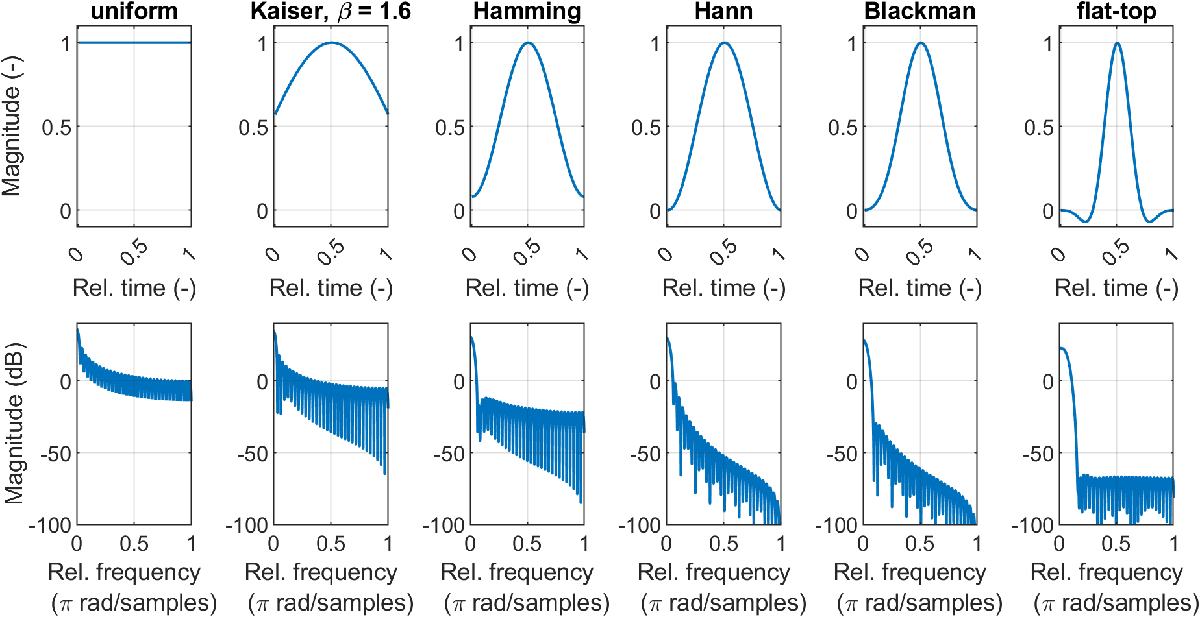

**Figure 2**: Shape and magnitude response of window functions implemented in `autofft`.

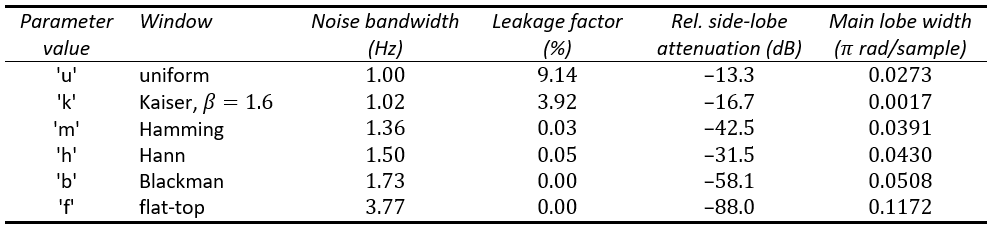

**Table 1: **Some characteristics of window functions implemented in `autofft`.

### Overlapping

The analysed signal is divided into equally long segments whose length determines the frequency resolution. Two adjoining segments may or may not overlap. The amount of overlap determines the total number of segments. Assuming that $o$ is the overlap length in samples, the total number of segments is

 
$$N_{\textrm{seg}} =\left\lfloor \frac{N_s -o}{n_s -o}\right\rfloor ,$$


where $N_s$ is the a total number of samples, $n_s$ is the number of samples in one segment and$\left\lfloor \right\rfloor$is the [floor function](https://en.wikipedia.org/wiki/Floor_and_ceiling_functions) [8]. The relation allows for using negative overlaps. However, the negative overlaps cause data loss because there are samples between two successive segments, which are omitted from the time-frequency analysis. Too high overlaps are lowered automatically per the relation


$$\textrm{If}\;o\ge n_s \Rightarrow o=n_s -1\ldotp$$
 

The optimal overlap depends on the used window function, which adds weights to individual samples. The overlap can be selected so that the data loss is avoided and the overall weighting is flat (except parts at the beginning and end of the signal). The following rules, shown in fig. 3, apply for individual windows:

- **Uniform window:** 0 % overlap guarantees a truly flat overall weighting of the data. Any other overlap results in a step-wise overall weighting at the beginning and end of the signal.

- **Kaiser window with** $\beta =1\ldotp 6:$ A reasonably flat overall weighting of the data can be achieved only with 99 % and higher overlaps. More common values, including 66.67 %, 75 % and 80 %, result in a non-uniform weighting. This ripple increases the uncertainty of the analysed magnitudes.

- **Hamming window:** a flat overall weighting of the data is achieved with overlaps 66.67 %, 75 %, 80 % and higher. Note that due to the non-zero values at the boundaries of the Hamming window, a ripple in the form of outlying samples can appear, see fig. 3. This ripple appears, e.g. if the overlap is 66.67 %, but the segment length in samples is indivisible by 3.

- **Hann window:** a flat overall weighting of the data is achieved with overlaps 66.67 %, 75 %, 80 % and higher.

- **Blackman window:** a flat overall weighting of the data is achieved with overlaps 66.67 %, 75 %, 80 % and higher.

- **Flat-top window:** a reasonably flat overall data weighting is achieved with overlaps of 80 % and higher.

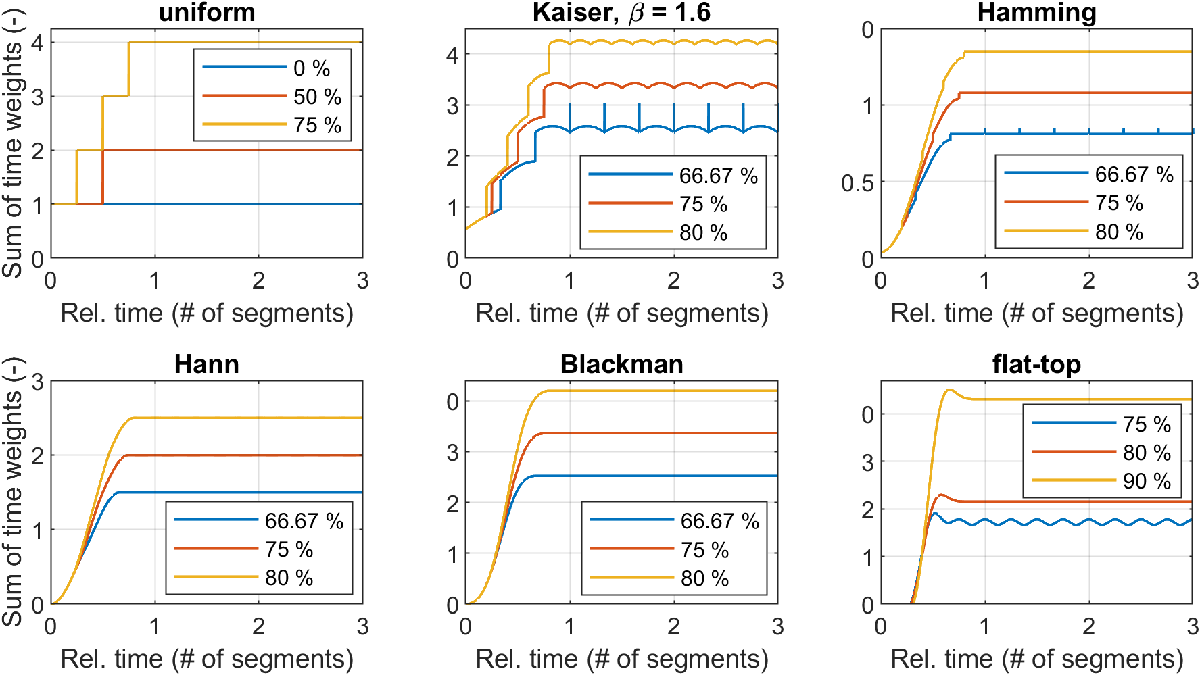

**Figure 3**: Overall weighting of the data for window functions implemented in `autofft` with various amounts of the overlap.

`'OverlapLength'`** — Number of overlapped samples of two successive segments**

`50 % of 'FFTLength' (default) | integer lower than 'FFTLength'`

`'OverlapLength'` indicates the overlap length in samples $o$. If both `'OverlapLength'` and `'OverlapPercentage'` are provided, then `'OverlapPercentage'` is omitted. 

**Data type:**` double | single`

`'OverlapPercentage'`** —  Overlap percentage of two successive segments**

`50 (default) | <0, 100>`

`'OverlapPercentage'` indicates the overlap length relative to the length of the window $o_{\textrm{rel}}$. If this parameter is provided, the overlap length in samples is computed as


$$o=\left\lbrack \frac{{o_{\textrm{rel}} \cdot \;n}_s }{100}\right\rbrack ,$$


where $n_s$ is the number of samples in one segment and $\left\lbrack \right\rbrack$ is the round function.

**Data type:**` double | single`

### Frequency-domain differentiation and integration

`'jwWeigthing'`** — Frequency-domain post-weighting**

`'1' (default) | '1/jw2' | '1/jw' | 'jw' | 'jw2'`

A frequency-domain post-weighting can be used to estimate derivation or integral of a measured signal. The post-weighting is beneficial if e.g. velocity of vibration has to be estimated from the measured acceleration. The post-weighting is performed before the spectral averaging.

The single integration of the DFT at the $i$-th spectral line is computed using the formula


$${\bar{X} }_i =\frac{X_i }{\;\mathrm{j}\cdot \;2\cdot \pi \cdot f_i \;},$$


where $X_i$ is a complex number representing the DFT at the $i$-th spectral line, $f_i$ is the frequency of the $i$-th spectral line in Hz and$\;\mathrm{j}\;$is the imaginary unit.

Similarly, the single differentiation of the DFT at the $i$-th spectral line is computed using the formula


$${\bar{X} }_i ={\mathrm{j}\cdot 2\cdot \pi \cdot f_i \cdot X}_i \ldotp$$


**Remark 3:** The frequency-domain integration should be used as a last resort to determine the integral of the measured signal, because it tends to overestimate magnitudes at low frequencies.

Following frequency-domain post-weighting modes are available:

- `'1/jw2'` or `'double integration'` performs a double integration.

- `'1/jw'` or `'single integration' `performs a single integration.

- `'1'` or `'none'` leaves the resulting DFT as is.

- `'jw'` or `'single differentiation'` performs a single differentiation.

- `'jw2'` or `'double differentiation'` performs a double differentiation.

**Data type:**` char | string`

### Spectral averaging

`'Averaging'`** — Algorithm for spectral averaging**

`'linear' (default) | 'energy' | 'max' | 'median' | 'min' | 'var' | 'none'`

This parameter enables averaging of the estimated DFTs and also serves as a switch between the output in the form of the averaged DFT or STFT.  If the avearging is enabled, the output is averaged in the frequency domain. The averaging takes place before the computation of spectral units and works with unscaled magnitudes of a linear spectrum. This implementation eliminates phase shifts of the frequency components in the individual segments and ensures that the averages of various spectral units are convertible. `autofft` averages absolute values of the DFT in the frequency range given by the `'LowPassFrequency'` parameter. This implementation is considerably faster than the original Welch's method, since the absolute value of the DFT can be computed more quickly than the autospectrum or power spectral density. However, it yields slightly different magnitudes since $\sum_{\left(i\right)} {\left(x_i \right)}^2 \not= {\left(\sum_{\left(i\right)} x_i \right)}^2$. For this reason, the Welch's method is also implemented.

The following averaging algorithms are available (all equations assume that $s_{j,i}$ is a magnitude located at the $j$-th spectral line in the $i$-th segment):

- `'linear'` applies linear averaging which places equal emphasis on all realizations of the DFT, i.e. ${\bar{s} }_j =\frac{1}{N_{\textrm{seg}} }\sum_{i=1}^{N_{\textrm{seg}} } s_{j,i}$.

- `'energy'`, `'rms'` or `'welch'` calculates the averages of the squared values the magnitudes, i.e.${\bar{s} }_j =\sqrt{\frac{1}{N_{\textrm{seg}} }\sum_{i=1}^{N_{\textrm{seg}} } {\left(s_{j,i} \right)}^2 }$. Due to the nature of the used eqution, this averaging mode puts more weight to the higner magnitudes and it is commonly used in acoustic applications.

- `'max', 'maximum'` or `'peak'`  holds the *maximum magnitude* at the$j$-th spectral line, i.e. ${\bar{s} }_j =\max \left(s_{j,1} ,\ldotp \ldotp \ldotp ,s_{j,N_{\textrm{seg}} } \right)$. This averaging mode can be used to estimate the worst case scenario in periodic signals or to evaluate the upper envelope of broad-band signals.

- `'med'` or `'median'` holds the *median* at the$j$-th spectral line, i.e. ${\bar{s} }_j =\textrm{median}\left(s_{j,1} ,\ldotp \ldotp \ldotp ,s_{j,N_{\textrm{seg}} } \right)$. This averaging mode is useful to estimate mean values of stationary signals corrupted by transients.

- `'min'` or `'minimum'` holds the *minimum magnitude* at the$j$-th spectral line, i.e. ${\bar{s} }_j =\min \left(s_{j,1} ,\ldotp \ldotp \ldotp ,s_{j,N_{\textrm{seg}} } \right)$. This averaging mode is usually used to evaluate the lower envelope of broad-band signals.

- `'var'` or `'variance'`  computes the *variance* at the$j$-th spectral line, i.e ${\bar{s} }_j =\frac{1}{N_{\textrm{seg}} -1}\sum_{i=1}^{N_{\textrm{seg}} } {\left|s_{j,i} -\mu \;\right|}^2$ where $\mu =\frac{1}{N_{\textrm{seg}} }\sum_{i=1}^{N_{\textrm{seg}} } s_{j,i}$. The variance is essential to evaluate the dispersion of broad-band signals and for the classification of the components with the constant frequency and time-varying magnitude. The variance algorithm is not available for power spectrum and power spectral density.

- `'none'` disables the spectral averaging and returns the STFT of the input.

**Data type:**` char | string`

### Spectral units

#### Absolute units

`'SpectralUnit'`** — Engineering unit of the output spectra**

`'pow' (default) | 'rms' | 'pk' | 'pp' | 'psd' | 'rsd'`

Various types of the analysed signals require different spectral units. `autofft` evaluates teh spectral unit after the spectral averaging is performed. The available spectral units include:

- `'pow'` or `'power'` estimates *power spectrum* (also called *autospectrum*). This spectral unit is useful for analysing general stationary deterministic signals. Per definition, the power spectrum is the square of the root mean square value.

- `'rms'` estimates the *root mean square magnitude *of the signal. This spectral unit is commonly used for analysing the velocity of vibration.

- `'pk'` or `'0-pk'` estimates the *peak magnitude* of the signal. This spectral unit is commonly used for analysing the acceleration of vibration.

- `'pp'` or `'pk-pk'` estimates the *peak-to-peak magnitude* of the signal. This spectral unit is commonly used for analysing the displacement of vibration.

- `'psd'` or `'asd'` estimates *power spectral density* of the analysed signal. The power spectral density is a correct unit for displaying broad-band random signals. If applied on the broad-band signal, its magnitude is independent on the frequency resolution of the DFT.

- `'rsd'` or `'rmssd'` is equal to the *square root of the power spectral density*. Similarly to the PSD, it is used for analysing of broad-band signals.

**Data type:**` char | string`

#### Decibels

`'dbReference'`** — Reference value of the decibel scale**

` positive scalar | 0 | NaN (default)`

`'dbReference'` controls whether the computed spectrum is returned in the absolute units or decibels. If `'dbReference'` is a positive scalar, the absolute units are converted to the decibels using the equations below (assuming $s_{\textrm{ref}}$ is the user-defined reference value):

- Power quantities, i.e. `'rms'`, `'0-pk'`, `'pk-pk'` and `'rmssd'`,  use transform $L_{s,j} =10\;\log_{10} \left(\frac{s_{j\;} }{s_{\textrm{ref}} }\right)$.

- Root-power (field) quantities, i.e. `'power'` and `'psd'`,  use transform $L_{s,j} =10\;\log_{10} \left(\frac{s_j^2 }{s_{\textrm{ref}}^2 }\right)=20\;\log_{10} \left(\frac{s_{j\;} }{s_{\textrm{ref}} }\right)$.

If `'dbReference'` is 0, $s_{\textrm{ref}}$ is computed internally so that the maximum value of the results is 0 dB.

Finally, if `'dbReference'` is `NaN`, the results are evaluated in the absolute units.

**Data type:**` double | single`

### Data visualisation

`'PlotLayout'`** — Layout used to visualise results**

`'none' (default - see below) | 'separated' (default - see below) | 'stacked' | 'tiled'`

`'PlotLayout'` controls, which layout is used to visualise results. Following layouts can be used:

- `'none'` - The `autofft` function does not visualise any results.

- `'separated'` - Each spectrum or spectrogram is visualised in a separate figure.

- `'stacked'` - All results are visualised in single axes. This option can be used if the results includes only autospectra. If the results consist of spectrograms and the `'stacked'` layout is specified, the function for data visualisation changes it to `'tiled'`.  

- `'tiled'` - Creates a panel for each autospectrum or spectrogram. All panels ale located in a single figure. This option uses the `tiledlayout` function. However, if `tiledlayout` is not available, the panels are generated using the `subplot` function.

The default value of the `'PlotLayout'` parameter depends on the way used to call the `autofft` function:

- `'none'` is the default value if the `auttofft` function is called with no output variables, and

- `'separated'` is the default value if the `auttofft` function is called with at least one output variable.

**Data type:**` char | string`

`'EngineeringUnit'`** — A unit of measure of the input data**

`'EU' (default) | user-defined string`

This parameter specifies a unit of measure of the input data. It is used to generate labels of vertical axes and colorbars during data visualisation. For more information, see data visualisation example.

**Data type:**` char | string`

## References

- SÖNNERLIND, H. *Finding Answers to the Tuning Fork Mystery with Simulation* [online]. Stockholm (Sweden): COMSOL, 2018 [cit. 2022-06-19]. Available at: [https://www.comsol.com/blogs/finding-answers-to-the-tuning-fork-mystery-with-simulation/](https://www.comsol.com/blogs/finding-answers-to-the-tuning-fork-mystery-with-simulation/) 

- RANDALL, R. B. *Frequency Analysis*. 3rd edition. Naerum (Denmark): Brüel & Kjaer, 1987.

- *PULSE LabShop* [software]. v23.0.0. Naerum (Denmark): Brüel & Kjaer, 2020.

- *LabView *[software]. v2019. Austin (TX): National Instruments, 2019.

- *Simcenter Testlab* [software]. v2019.1. Munich (Germany): Siemens, 2019.

- Hann function. In: *Wikipedia: the free encyclopedia* [online]. San Francisco (CA): Wikimedia Foundation, 2001- [cit. 2022-06-19]. Available at: [https://en.wikipedia.org/wiki/Hann_function](https://en.wikipedia.org/wiki/Hann_function) 

- makima. In: *MathWorks: Help Center* [online]. Natick (MA): MathWorks, 1994-2022 [cit. 2022-06-19]. Available at: [https://www.mathworks.com/help/matlab/ref/makima.html](https://www.mathworks.com/help/matlab/ref/makima.html)

- Floor and ceiling functions. In: *Wikipedia: the free encyclopedia* [online]. San Francisco (CA): Wikimedia Foundation, 2001- [cit. 2022-06-19]. Available at: [https://en.wikipedia.org/wiki/Floor_and_ceiling_functions](https://en.wikipedia.org/wiki/Floor_and_ceiling_functions) 

## Appendix A: Road Map

Features which I plan to implement in future releases of `autofft` (in no specific order):

- support for tables and timetables,

- new spectral units (Fourier spectrum, energy spectral density)

- new analysis modes (frequency zoom, envelope analysis, Bode plot),

- advanced multi-buffering and triggering,

- wrappers that apply `setup` to standard Matlab functions,

- GUI (?)

## Appendix B: Historical Release Notes

- **v1.5.4:** *Bug fix*: Automatic plotter no longer uses white backgroud color in R2025a dark mode.

- **v1.5.4:** *Bug fix*: Plotting error when the user selected tiled layout for time-frequency analysis results from only one channel has been fixed.

- **v1.5.4:** *Code optimisation*: Code optimisation: Evaluation of magnitude and spectral unit optimised. Other minor optimisations implemented and code refactored. Implemented changes reduced CPU time by up to 35 %.

- **v1.5.4:** *Code optimisation*: Error handling during filtering has been improved.

- **v1.5.4:** *Documentation*: Introduction has been revised.

- **v1.5.3:** *New functions:* The results are now visualised automatically or manually using `'PlotLayout'` and `'EngineeringUnit'` parameters.

- **v1.5.3:** *Changed functionality:* `'HighPassFrequency'` parameter now also accepts a filter object or numerator and denominator coefficients `b` and `a`. This feature allows experienced users to use their own filters and store them in the `setup` structure array.

- **v1.5.3:** *Documentation:* New example added.

- **v1.5.3:** *Documentation*: Nomenclature have been unified and simplified.

- **v1.5.2: ***Changed functionality: *The package no longer requires the Signal Processing Toolbox™.

- **v1.5.2: ***Changed functionality: *A first-order Butterworth digital filter is now used for high-pass filtering rather than a first-order elliptic filter.

- **v1.5.2:** *New functions*: The package is now distributed with functions that can construct Blackman-Harris, flat-top, Hamming, Hann, Kaiser and uniform windows and can design an n-th order Butterworth digital filter. These functions can be found in `+utilities` directory.

- **v1.5.1:** *Code optimisation:* The STFT is now computed more efficiently.

- **v1.5.1:** *Bug fix:* In same cases, times for the STFT were evaluated more than once. This has been fixed.

- **v1.5.0: ***New functionality:* The output spectra can be returned in decibel scale using the `'dbReference'` parameter.

- **v1.5.0: ***New function:* A `freqWeight` function, which applies frequency weighting filters to the power spectrum, is now included in the package.

- **v1.5.0: ***Documentation:* New example added.

- **v1.5.0: ***Code optimisation:* Times at which the STFT is evaluated are computed more efficiently.

**v1.4**

- **v1.4.1:** *Bugfix:* Sampling frequency is now estimated more accurately if the time stamps have poor resolution or high uncertainty.

- **v1.4.0: ***New functionality:* Analyser mode can now be changed using the `'Mode'` parameter. Currently available modes include one-sided and two-sided spectra.

- **v1.4.0: ***Documentation:* Section Analyser resolution has been reworked.

- **v1.4.0: ***Code optimisation:* Spectral averaging is now performed employing unscaled linear spectra. This implementation accelerates the spectral averaging up to 30 %, decreasing CPU time noticeably.

- **v1.4.0: ***Bugfix:* `'LowPassFrequency'` is now automatically decreased if higher than the Nyquist frequency.

**v1.3**

- **v1.3.1:** *Bugfix:* When `'jwWeigthing'` is set to derivation or integration, times `t` are computed properly.

- **v1.3.0: ***Syntax change:* `[s, f, t, setup] = autofft(___)` returns the times `t` at which the STFT is evaluated.

- **v1.3.0: ***Syntax change:* The setup of the FFT analyser is now specified using `setup` structure; parameters used in the `setup` structure have the same names as parameters used in `pspectrum` and `stft` functions. Output variable `setup `can also be used as input. The structure `fftset` used in the previous versions can still be used to specify the analyser setup. However, `fftset` is no longer documented.

- **v1.3.0: ***New functionality:* Overlap length can be now set in samples using the `'OverlapLength'` parameter.

- **v1.3.0: ***Functionality change:* The default shape factor of the Kaiser window is now $\beta =1\ldotp 6$ instead of $\beta =0\ldotp 5$.

- **v1.3.0: ***Documentation:* A brand new user manual is a part of this release.

- **v1.3.0: ***Bugfix:* `'OverlapPercentage'` 100% or higher is now automatically decreased to a realistic value.

- **v1.3.0: ***Bugfix:* All windows are now treated as column vectors. Row vectors could cause an error during the application of a window to data.

**v1.2**

- **v1.2.5.1 **- *Bugfix:* Outputs which appeared twice in `setup` now appear only once.

- **v1.2.5 **- *New functionality:* An optional highpass filtering has been implemented.

- **v1.2.4.2** - *Bugfix:* Overlap length (in samples) returned in setup is now correct.

- **v1.2.4.1** - *Bugfix:* Error occuring during the estimation of auto spectrum has been fixed.

- **v1.2.4:** *Syntax change:* Results of the STFT of multiple signals are now returned as 3D array rather than cell array of 2D arrays.

- **v1.2.4:** *New functionality:* New types of averaging:* median filter *and *variance of spectral unit*.

- **v1.2.4:** *Documentation* has been improved.

- **v1.2.4:** *Code optimisation:* A new method for the spectral averaging has been implemented, which improved performance significantly.

- **v1.2.4:** *Bugfix:* Accuracy of PSD and RMSSD estimates has been slightly improved.

- **v1.2.4:** *Bugfix:* Dealing with a content at the Nyquist frequency has been improved.

- **v1.2.3:** *Syntax change:* The analyser setup can be returned as an output variable.

- **v1.2.3:** *New functionality:* User can define frequency resolution of the analyser using `'df'` parameter.

- **v1.2.3:** *New functionality:* The window function can be directly specified as a vector.

- **v1.2.3:** *User experience:* Warning messages are now displayed if user specified paramters are changed internally.

- **v1.2.2.1** - *Bugfix:* Error occuring during peak hold averaging has been fixed.

- **v1.2.2:** *New functionality:* The Kaiser-Bessel window parameter (beta) can now be specified.

- **v1.2.2:** *Bugfix:* Autospectrum is now properly square of RMS rather than square of 0-Pk.

- **v1.2.2:** *Bugfix:* Relations for evaluation of PSD and RMSPSD now consider the noise power bandwidth of the used window function. 

- **v1.2.1:** *Syntax change:* Options for `'unit'` and `'peak`' have been merged (into `'unit'`).

- **v1.2.1:** *New functionality:* Maximum frequency can now be specified using `'lowpass'` parameter.

- **v1.2.1:** *New functionality:* New types of averaging have been added: *no averaging*, *energy averaging* and *minimum value hold*.

- **v1.2.1:** *Bugfix:* Relations for evaluation of PSD and RMSPSD have been improved.

- **v1.2.1:** *Bugfix:* Dealing with a content at the Nyquist frequency has been improved.

- **v1.2.0: ***Syntax change:* Input parameters are now specified in a structured variable. Due to this change, v1.2.0 is not compatible with the previous releases.

**v1.1**

- **v1.1.2:** *Syntax change:* Input parameter `xs` can now be an array.

- **v1.1.1:** *Bugfix:* Performance has been improved.

- **v1.1.1:** *Bugfix:* Handling of input vectors with the even number of samples has been improved.

- **v1.1.0: ***Syntax change:* Parameters `'nwin'` and `'overlap'` can now be skipped by user.

- **v1.1.0: ***Bugfix:* Relations for evaluation of spectral units now consider the influence of non-uniform windows.

## Appendix C: License terms

**BSD 3-Clause License**

Copyright © 2017-2025, Luboš Smolík, Jan Rendl, Roman Pašek

All rights reserved.

Redistribution and use in source and binary forms, with or without modification, are permitted provided that the following conditions are met:

- Redistributions of source code must retain the above copyright notice, this list of conditions and the following disclaimer.

- Redistributions in binary form must reproduce the above copyright notice, this list of conditions and the following disclaimer in the documentation and/or other materials provided with the distribution.

- Neither the name of the copyright holder nor the names of its contributors may be used to endorse or promote products derived from this software without specific prior written permission.

THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS" AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE ARE DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT HOLDER OR CONTRIBUTORS BE LIABLE FOR ANY DIRECT, INDIRECT, INCIDENTAL, SPECIAL, EXEMPLARY, OR CONSEQUENTIAL DAMAGES (INCLUDING, BUT NOT LIMITED TO, PROCUREMENT OF SUBSTITUTE GOODS OR SERVICES; LOSS OF USE, DATA, OR PROFITS; OR BUSINESS INTERRUPTION) HOWEVER CAUSED AND ON ANY THEORY OF LIABILITY, WHETHER IN CONTRACT, STRICT LIABILITY, OR TORT (INCLUDING NEGLIGENCE OR OTHERWISE) ARISING IN ANY WAY OUT OF THE USE OF THIS SOFTWARE, EVEN IF ADVISED OF THE POSSIBILITY OF SUCH DAMAGE.